% SET OPTIONS
KneipA_on = false;
KneipN_on = false;
KneipO_on = false;
Grunert_on = false;
MatlabPnP_on = false;
importLogs = true;

p3pToRun = {'KneipN'};

%File directories
%imgFolder = "C:\Users\alyss\OneDrive - University of Cape Town\Sandbox\PnP\Verification\Traj-0001\Few\Left";
% imgFolder = "C:\Users\alyss\OneDrive - University of Cape Town\Sandbox\PnP\Verification\Traj-0001\Few";
%imgFolder = "C:\Users\alyss\OneDrive - University of Cape Town\Sandbox\PnP\Verification\Traj-0001\Few\Up-right";
%imgFolder = "C:\Users\alyss\OneDrive - University of Cape Town\Sandbox\PnP\Verification\Traj-0001\Few\Down";
%imgFolder = "C:\Users\alyss\OneDrive - University of Cape Town\Sandbox\PnP\Verification\Traj-0002\Few";

%Traj-0003
%imgFolder = "C:\Users\alyss\OneDrive - University of Cape Town\Sandbox\PnP\Verification\Traj-0003\Few";
%logFile = "C:\Users\alyss\OneDrive - University of Cape Town\Sandbox\PnP\Verification\Traj-0003\camPose.mat";

%Traj-0004:
imgFolder = "C:\Users\alyss\OneDrive - University of Cape Town\Sandbox\PnP\Verification\Traj-0004\Few";
logFile = "C:\Users\alyss\OneDrive - University of Cape Town\Sandbox\PnP\Verification\Traj-0004\camPose.mat";

% INITIALISE CONSTANTS

%INITIALISE WORLD MAP
map = load('C:\Users\alyss\OneDrive - University of Cape Town\Sandbox\PnP\Pnp_solver\GitClone\Resources\map.mat');

%Camera variables
%K = [1274.58238813250 0 627.693937913345; 0 1273.36371905619 405.441250468717; 0 0 1]; %23 mm calibration
%K=   [605.8071 0 316.6903; 0 608.4646 256.6409; 0 0 1.0000]; %31 mm calib
K = [1109 0 640; 0 1109 360; 0 0 1]; %virtual camera

%Checkerboard variables
X_pnts_W = map.worldObjectStruct.checkers.Corners;
checkerSize = map.worldObjectStruct.checkers.NumSquares;
checkerEdgeLength = map.worldObjectStruct.checkers.SquareSize; %mm
checker_w_mm = 31*checkerSize(2);
checker_h_mm = 31*checkerSize(1);

%Known coordinate transformations (mapping)
% Rt_board2W = [0 -1 0 (checker_h_mm/2 -checkerEdgeLength); 
%               -1 0 0 (checker_w_mm/2 -checkerEdgeLength); 
%               0 0 1 0];
R_unreal2World = [1 0 0; 0 1 0; 0 0 1];


%other variables
p3pResult = struct();



%X_pnts_W = p3pFuncs.calcCheckerEdgeCoords_W(checkerSize, checkerEdgeLength, Rt_board2W)


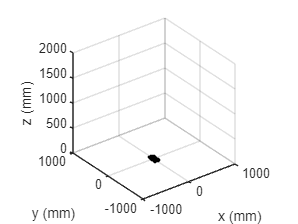

%INTIALISE PLOT
close all
%trajFig = figure();
%worldAx = p3pPlotting.initPlot(trajFig, [-1000,1000], [-1000,1000], [0 2000]);
%p3pPlotting.addCheckerboard(worldAx, X_pnts_W);

%ADD TRAJECTORIES
plotStruct = initPlots('KneipN', 'Matlab', 'Verification');
p3pPlotting.addCheckerboard(plotStruct.traj.Ax, X_pnts_W);


% if KneipA_on == true
%     [lineObj_KneipA, axTextArr_KneipA, axLineArr_KneipA] = p3pPlotting.addTraj(worldAx, 'Kneip (Alyssa)', '-or', '-r');
% end
% if KneipN_on ==true
%     %[lineObj_KneipN, axTextArr_KneipN, axLineArr_KneipN] = p3pPlotting.addTraj(worldAx, 'Kneip (Nagano)', '-om', '-m');
%     plotStruct = initPlots('KneipN');
%     trajFig = plotStruct.traj.Fig;
%     worldAx = plotStruct.traj.Ax;
%     lineObj_KneipN = plotStruct.traj.plotLines.('KneipN').line;
%     axTextArr_KneipN = plotStruct.traj.plotLines.('KneipN').frameText;
%     axLineArr_KneipN = plotStruct.traj.plotLines.('KneipN').frameLines;
% 
% 
% end
% if KneipO_on ==true
%     [lineObj_KneipO, axTextArr_KneipO, axLineArr_KneipO] = p3pPlotting.addTraj(worldAx, 'Kneip (Original)', '-ok', '-k');
% end
% if MatlabPnP_on == true
%     [lineObj_Mat, axTextArr_Mat, axLineArr_Mat] = p3pPlotting.addTraj(worldAx, 'Matlab P3P', '-ob', '-b');
% end
% if Grunert_on ==true
%     [lineObj_Grun, axTextArr_Grun, axLineArr_Grun] = p3pPlotting.addTraj(worldAx, 'Grunert', '-oc', '-c');
% end
% if importLogs == true
%     [lineObj_Ver, axTextArr_Ver, axLineArr_Ver] = p3pPlotting.addTraj(worldAx, 'Logged', '-og', '-g');
% end

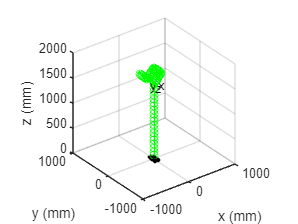

%IMPORT & PLOT LOGGED DATA
if importLogs ==true
    [rtHist_Ver, timeHist_ver] = imgFuncs.importSimLog(logFile,  R_unreal2World);
    lineObj_Ver = plotStruct.traj.plotLines.Verification.line;
    axTextArr_Ver=plotStruct.traj.plotLines.Verification.frameText;
    axLineArr_Ver = plotStruct.traj.plotLines.Verification.frameLines;
    p3pPlotting.updateTraj(lineObj_Ver, axTextArr_Ver, axLineArr_Ver, rtHist_Ver);
end

%IMPORT IMAGES
I_seq = zeros(1,1,1);
[I_seq, I_seq_times] = imgFuncs.importImageSeq(imgFolder);

%INITIALISE RT AND ERROR HISTORIES
% if KneipA_on == true
%     rtHist_KneipA = zeros(3,4,1);
%     errHist_KneipA= zeros(3,1);
% end
% if KneipN_on ==true
%     rtHist_KneipN = zeros(3,4,1);
%     errHist_KneipN= zeros(3,1);
% end
% if KneipO_on ==true
%     rtHist_KneipO = zeros(3,4,1);
%     errHist_KneipO= zeros(3,1);
% end
% if MatlabPnP_on == true
%     rtHist_Mat = zeros(3,4,1);
%     errHist_Mat= zeros(3,1);
% end
% if Grunert_on ==true
%   rtHist_Grun = zeros(3,4,1);
%   errHist_Grun= zeros(3,1);
% end

Working on frame 1
Working on frame 2
Working on frame 3
Working on frame 4
Working on frame 5
Working on frame 6
Working on frame 7


Discarding frame 7


Working on frame 8
Working on frame 9


Discarding frame 9


Working on frame 10
Working on frame 11
Working on frame 12


Discarding frame 12


Working on frame 13
Working on frame 14
Working on frame 15


Discarding frame 15


Working on frame 16
Working on frame 17


Discarding frame 17


Working on frame 18


Discarding frame 18


Working on frame 19
Working on frame 20
Working on frame 21
Working on frame 22
Working on frame 23
Working on frame 24


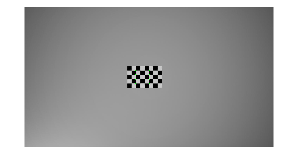

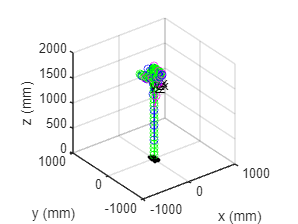

%RUN AND PLOT P3P FOR EACH CHECKERBOARD IMAGE
goodFrameCounter = 0;
for i=1:size(I_seq,3)

    disp(strcat("Working on frame ", string(i)));
    
    %Get current frame
    I=I_seq(:,:,i);
    imageArrSize = size(I);
    imageSize=imageArrSize(1:2);

    %Find checkerboard corners
    [x_pnts_i, checkerSize_detected] = detectCheckerboardPoints(I);
    x_pnts_i = transpose(x_pnts_i);

    %Display checkerboard
    if (checkerSize_detected(1) <= checkerSize(1)) || (checkerSize_detected(2) <= checkerSize(1)) 
        if i==1
            checkerFig = figure();
            checkerAx = axes('Parent', checkerFig);
            checkerImg = imshow(imgFuncs.markDetectedCheckers(I, x_pnts_i), 'Parent', checkerAx);
        else
            checkerImg.CData = (imgFuncs.markDetectedCheckers(I, x_pnts_i));
            drawnow;
        end 
    end
    

    %discard any frames where too few corners have been detected
    if (checkerSize_detected(1) ~= checkerSize(1)) || (checkerSize_detected(2) ~= checkerSize(2))
        disp(strcat("Discarding frame ", string(i)));
        continue
    end

    %Otherwise, continue:
    goodFrameCounter = goodFrameCounter +1;
    %Extract useful information
    time_I = I_seq_times(:,i); %time associated with frame
    [~,closestIndex] = min(abs(timeHist_ver-time_I));
    Rt_log_i = rtHist_Ver(:,:,closestIndex);


    %Run P3P
    p3pResult = runP3P(p3pResult, time_I, x_pnts_i, X_pnts_W, K, imageSize, checkerSize, 'KneipN', 'Matlab');
   % poseHist = poseHist_update(poseHist, newPose, newTime);
   % resultHist =
    plotStruct.traj = updatePlot(plotStruct.traj, p3pResult);

    %Update pose history
%    poseHist = 

    %Calculate error
    if importLogs == true
        p3pResult = calcRtError(p3pResult, rtHist_Ver, timeHist_ver);    
    end
% 



% 
% 
% 
% 
%     goodFrameCounter = goodFrameCounter +1;
%     if KneipO_on == true
%         Rt = p3pRun.KneipO(x_pnts_i, X_pnts_W, K, checkerSize);
%         rtHist_KneipO(:,:,goodFrameCounter) = Rt;
%         p3pPlotting.updateTraj(lineObj_KneipO, axTextArr_KneipO, axLineArr_KneipO, rtHist_KneipO);
%         %Update error
%         errHist_KneipO(:,goodFrameCounter) = p3pFuncs.getOrientErrArr(Rt_log_i, Rt, time_I);
%     end
%     if KneipA_on == true
%         Rt = p3pRun.KneipA(x_pnts_i, X_pnts_W, K, checkerSize);
%         rtHist_KneipA(:,:,goodFrameCounter) = Rt;
%         p3pPlotting.updateTraj(lineObj_KneipA, axTextArr_KneipA, axLineArr_KneipA, rtHist_KneipA);
%          %Update error
%         errHist_KneipA(:,goodFrameCounter) = p3pFuncs.getOrientErrArr(Rt_log_i, Rt, time_I);
%     end
% 
%     if KneipN_on == true
% 
% 
%         %test new function:
%         result = runP3P(x_pnts_i, X_pnts_W, K, imageSize, checkerSize, 'KneipN');
%         Rt =result.('KneipN').Rt;
% 
%         plotStruct.traj = updatePlot(plotStruct.traj, result);
% 
%          %Rt = p3pRun.KneipN(x_pnts_i, X_pnts_W, K, checkerSize);
%         %rtHist_KneipN(:,:,goodFrameCounter) = Rt;
%         %p3pPlotting.updateTraj(lineObj_KneipN, axTextArr_KneipN, axLineArr_KneipN, rtHist_KneipN);
% 
%         %Update error
%         errHist_KneipN(:,goodFrameCounter) = p3pFuncs.getOrientErrArr(Rt_log_i, Rt, time_I);
%     end
% 
%     if MatlabPnP_on == true
%         Rt = p3pRun.MatlabPnP(K,x_pnts_i, X_pnts_W, imageSize, 0.1);
%         rtHist_Mat(:,:,goodFrameCounter) = Rt;
%         p3pPlotting.updateTraj(lineObj_Mat, axTextArr_Mat, axLineArr_Mat, rtHist_Mat);
%          %Update error
%         errHist_Mat(:,goodFrameCounter) = p3pFuncs.getOrientErrArr(Rt_log_i, Rt, time_I);
%     end
% 
%     if Grunert_on == true
%         Rt = p3pRun.Grunert(x_pnts_i, X_pnts_W, K, checkerSize);
%         rtHist_Grun(:,:,goodFrameCounter) = Rt;
%         p3pPlotting.updateTraj(lineObj_Grun, axTextArr_Grun, axLineArr_Grun, rtHist_Grun);
%          %Update error
%         errHist_Grun(:,goodFrameCounter) = p3pFuncs.getOrientErrArr(Rt_log_i, Rt, time_I);
%     end
 end